
% NBE-E4000 Principles of Biomedical Engineering
% Template for Problem 1 of Exercise 1
%
% The example uses a three-shell head model made by me at MRC Cognition and
% Brain Sciences Unit, Cambridge, UK. The model was made using FLASH MR
% images, FreeSurfer, and MNE toolbox. If you would like to use this model
% for something that you wish to share or publish, please contact me.
%
% (c) Matti Stenroos 2016--2018, matti.stenroos@aalto.fi

clear
close all
% Put here the path of the folder, where you saved the plot
% functions that were shared in the Intro exercise. 
% You will need these functions also later.
plotfunctionpath='~/Documents/MATLAB/plotroutines/';
addpath(plotfunctionpath);

% put here the full path to the attached model file
modelfile='~/Documents/MATLAB/e1_files/e1_eegmodel';
load(modelfile,'m','noiseref','bmeshes','cmesh','L','eegsens');

% bmeshes:  triangle meshes for volume conductor model
%   cell array of structs that contain fields p, e, nop, noe (see below)
%
% cmesh:    cortical mesh, on which the sources are spanned; 8196 vertices
%   p: mesh vertices, [nop x 3] (source discretization points)
%   e: triangle description, [noe x 3] (indices to vertices)
%   nn:   cortical normal vector in each vertex, [nop x 3]
%   pinf: vertices for "inflated" mesh, [nop x 3] (commonly used for visualization)
%   curv: cortex curvature, [nop x 3] (commonly used for visualization)
%   nop: number of vertices, here 8196
%   noe: number of triangular elements, here 16384
%
% eegsens:  electrode positions and meshes for visualization; 70 electrodes
%   p:  electrode positions, [70 x 3]
%   mesh3d: mesh for 3D visualization of electrodes (p, e)
%   mesh2d: mesh for 2D visualization of electrodes (p, e)  
% L:        forward model, size(L) = (m,n) = (70 x 8196)
% m:        "measured" EEG, 100 time samples -> (70 x 100)
% noiseref: "measured" noise of the system, 200 samples -> (70 x 200)

## This "%%" is a "block separator". Press ctrl-enter to run the code in blocks.

first, demonstrate how spatial signals coming from a source atom look like & how to use the attached plot routines

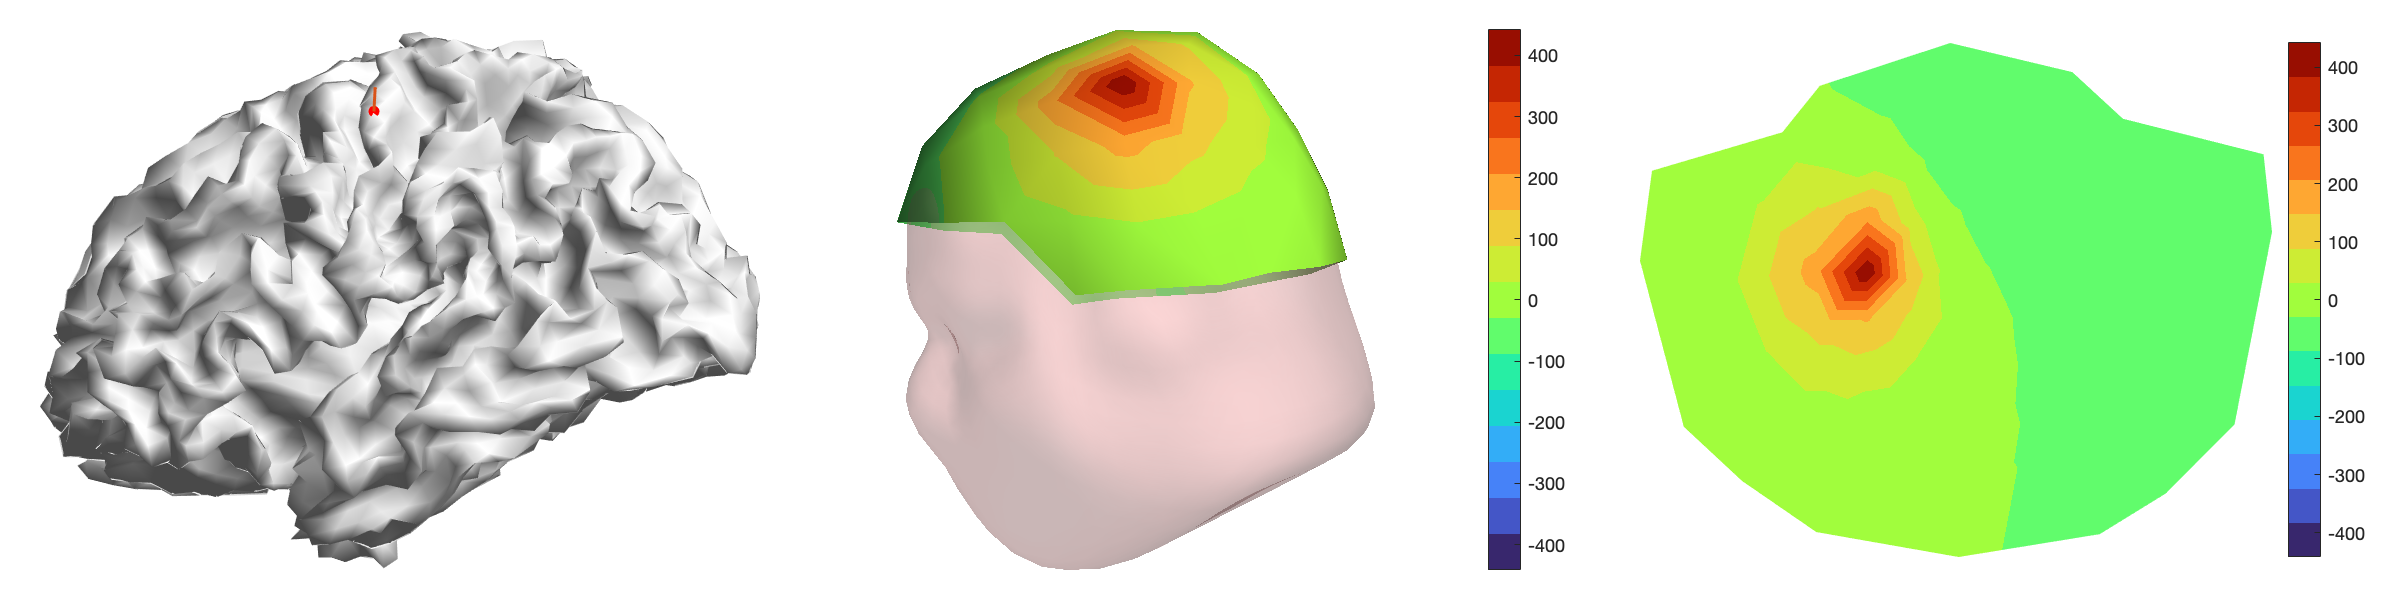

sourceind=1623; % pick one source position from the brain
topodata=L(:,sourceind); %scalp potential due to 1 Am source current dipole
fscale=[-1 1]*max(abs(topodata)); %scale the plot
plotwidth=400;plotheight=300; % set plot size

set(figure(1),'position',[0 100 3*plotwidth plotheight],'name','topoexample');clf;
CreateAxes(1,3,1);hold on %make a plot window
    % plot cortical mesh and show source position & orientation::
    PlotMesh(cmesh,'facecolor',[.95 .95 .95],'facealpha',1);
    PlotPoints(cmesh.p(sourceind,:),'r.',15);
    PlotDipoles(cmesh.p(sourceind,:),.01*cmesh.nn(sourceind,:),1.5,0);
CreateAxes(1,3,2);hold on
    % plot resulting signal topography on 3D electrode mesh & add scalp
    PlotDataOnMesh(eegsens.mesh3d,L(:,sourceind),'caxis',fscale,...
        'colorbar',1,'colormap',15);
    PlotMesh(bmeshes{end});
CreateAxes(1,3,3);hold on
    % plot resulting signal topography on 3D electrode mesh & add scalp
    PlotEMEGTopo2D(eegsens.mesh2d,L(:,sourceind),'caxis',fscale,...
        'colorbar',1,'colormap',15); 

% save the picture
saveflag=0;
savescale=.75;
savedir='~/Documents/MATLAB';
SaveCurrentFig(saveflag,savescale,savedir);

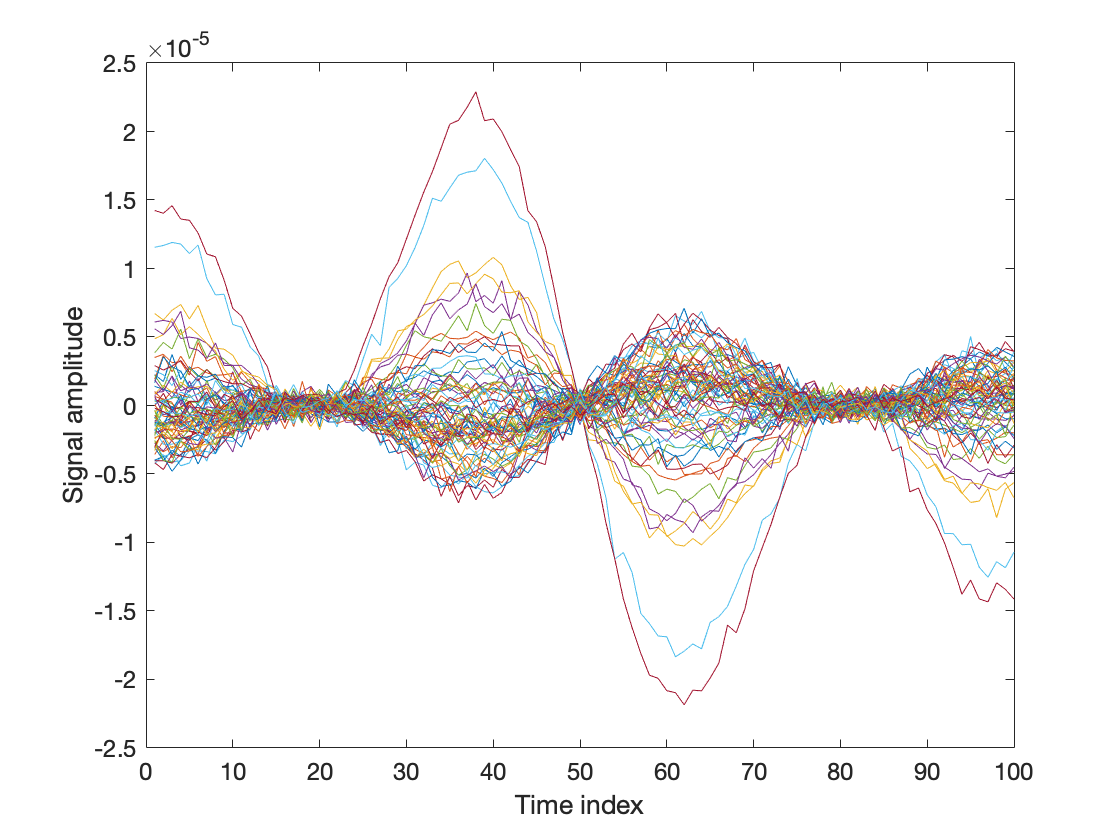

figure(2);clf; plot(m'); %plot the "measured" data as a "butterfly plot"
%add labels and set font sizes
fontsize_labels=14;
fontsize_axes=12;
xlabel('Time index','fontsize',fontsize_labels);
ylabel('Signal amplitude','fontsize',fontsize_labels);
set(gca,'fontsize',fontsize_axes);


% some tips for computing RMS...
m_rms=sqrt(mean(m.^2,2)); %compute RMS amplitude of the measurement for each channel
m_mrms=sqrt(mean(mean(m.^2,2))); %compute overall RMS amplitude of the measurement

## Work on th exercise starts here

This exersice is done in a colaboration with Hennah Terborg and Jan Andrys

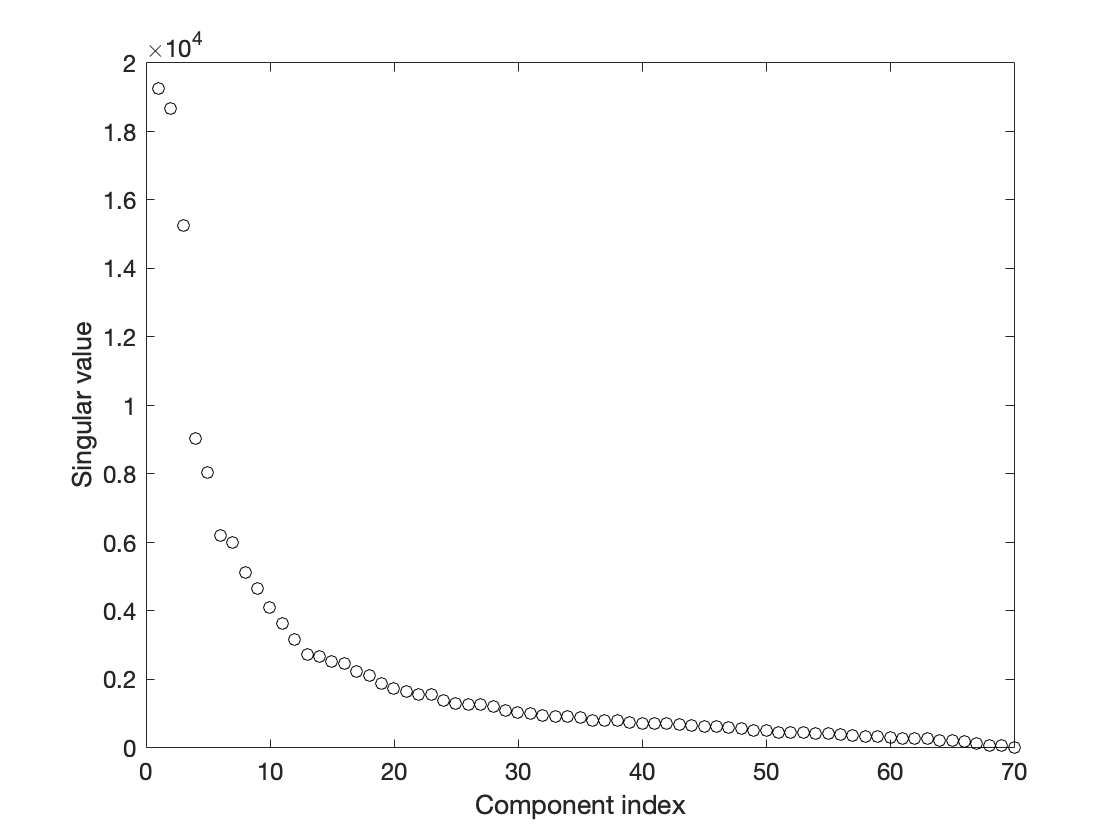

% First task: Caclulation of Singular Value Decomposition

Nfp=size(L,1); % number of sensors ("field points")
Nsp=size(L,2); % number of sources ("source points")
[U,S,V]=svd(L,'econ'); % ...svd --- write "help svd" to learn more
sigma=diag(S); % singular values

figure(3);clf; plot(sigma,'ko'); % plot of the singular values...
fontsize_labels=14;
fontsize_axes=12;
xlabel('Component index','fontsize',fontsize_labels);
ylabel('Singular value','fontsize',fontsize_labels);
set(gca,'fontsize',fontsize_axes);

## Plot first 6 components of U

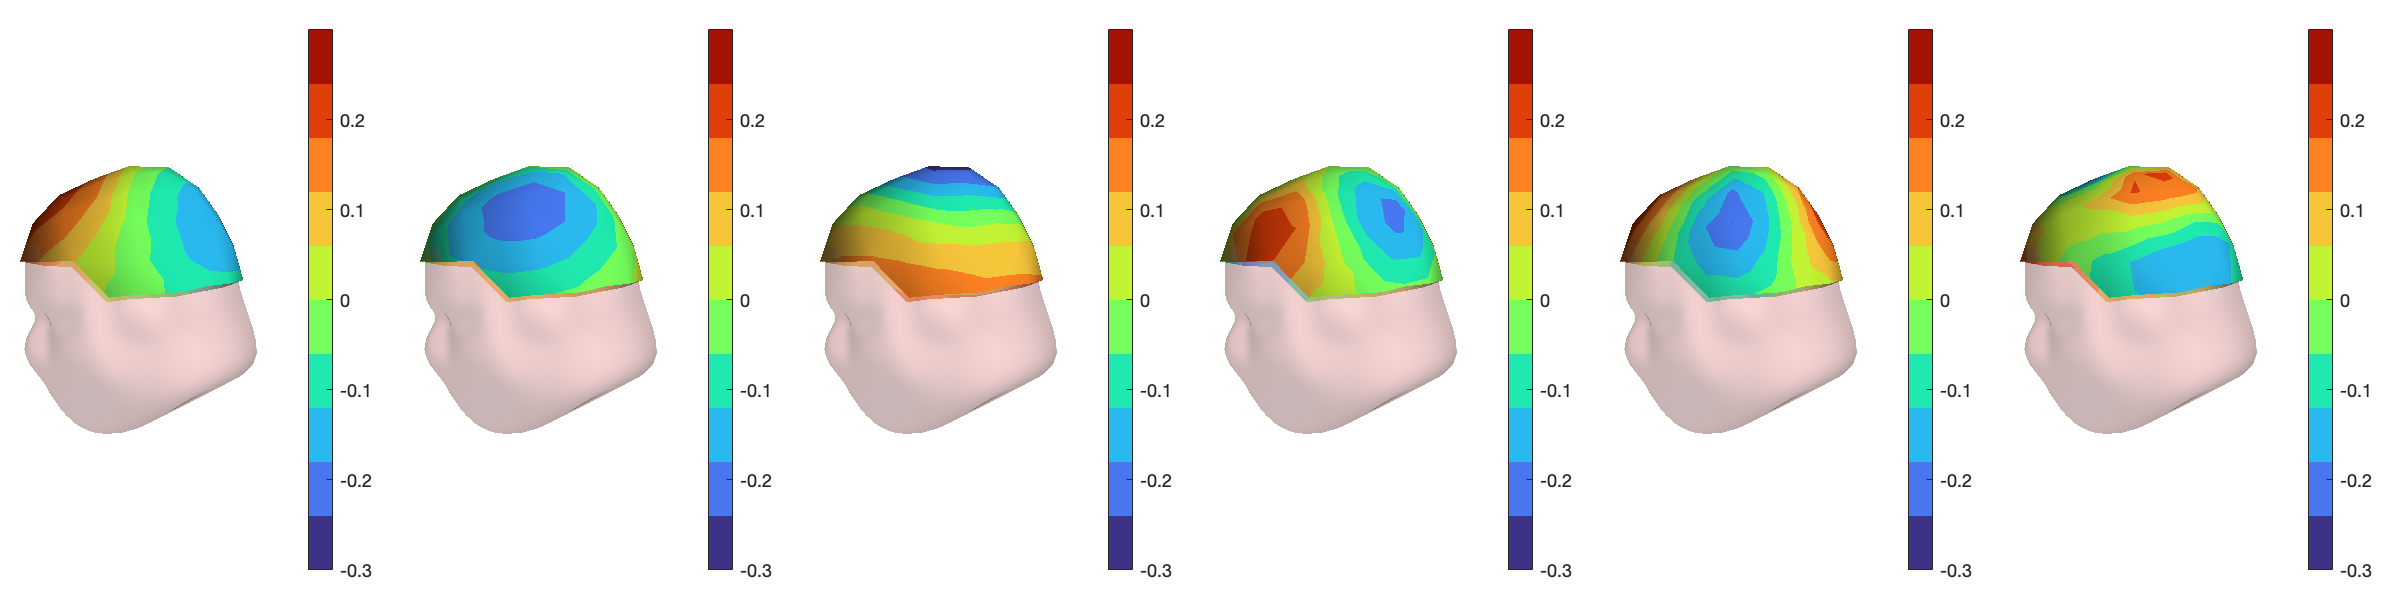

% First task: plot first 6 components of U

% Plot first 6 components of U plotted on sensor mesh
set(figure(3),'position',[0 100 3*plotwidth plotheight],'name','U components');clf;
for i=1:6
    CreateAxes(1, 6, i); hold on
    PlotDataOnMesh(eegsens.mesh3d, U(:, i), 'caxis', 0.3);
    PlotMesh(bmeshes{end});
end

## Plot first 6 components of V

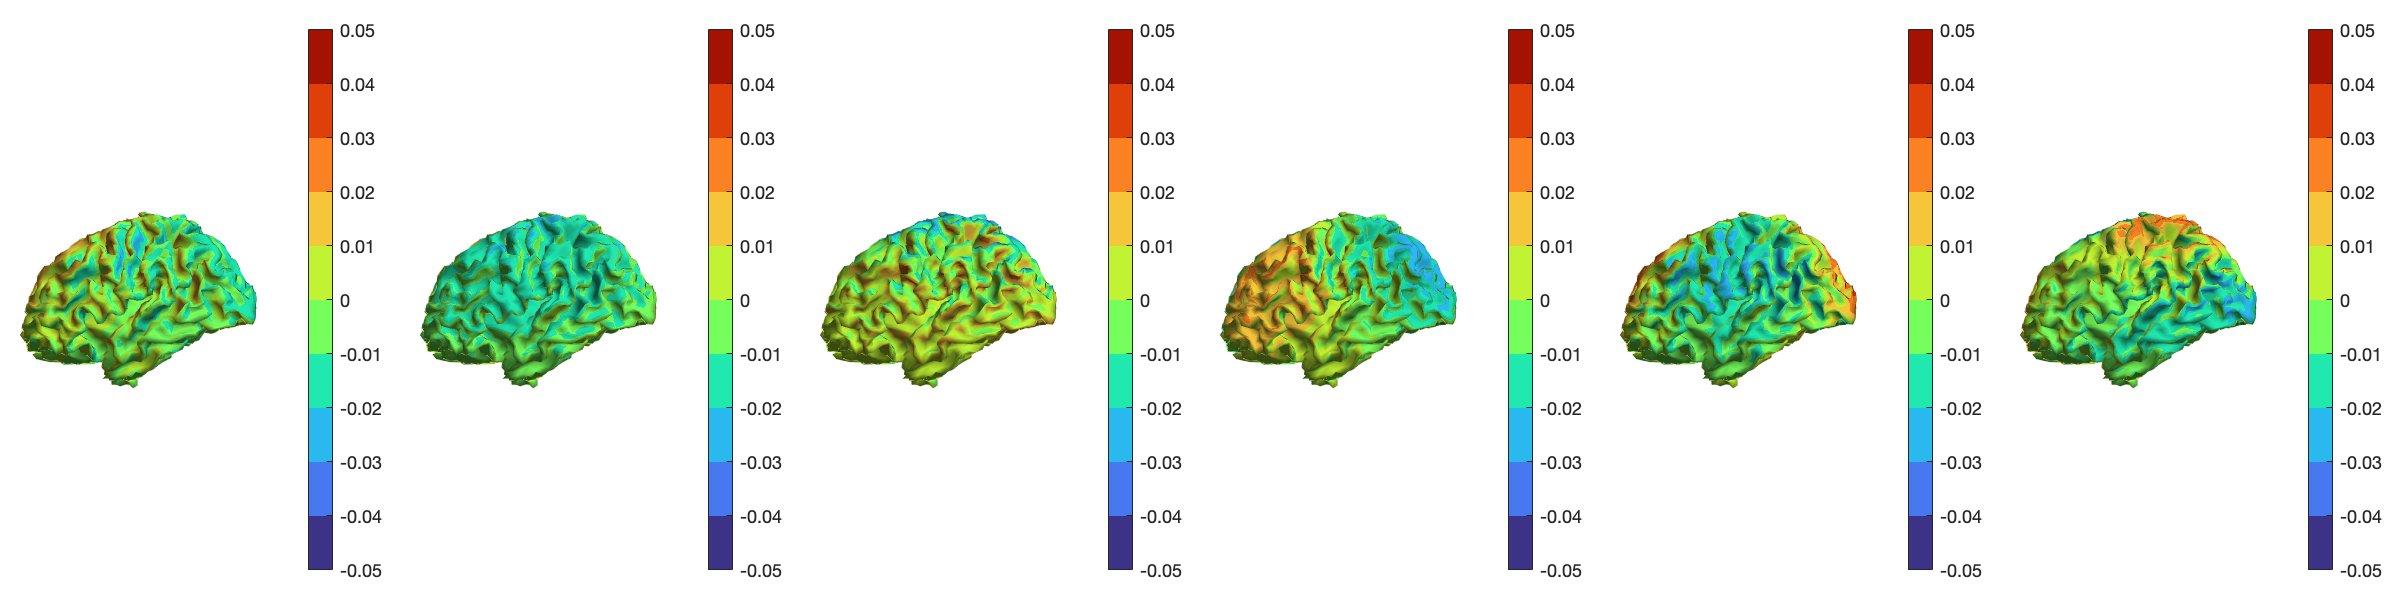

% Plot first 6 components of V to the brain (source) mesh - cmesh

% The V should be visualized on a mesh representing real brain not on the sensor mesh
sfv.p = cmesh.p;
sfv.e = cmesh.e;
set(figure(4),'position',[0 100 3*plotwidth plotheight],'name','V components');clf;
for i=1:6 
    CreateAxes(1,6,i);hold on
    % take 6 components and plot on mesh
    PlotDataOnMesh(sfv, V(:,i), 'caxis', 0.05);
end

### Project measurement and noise vectors to U space.

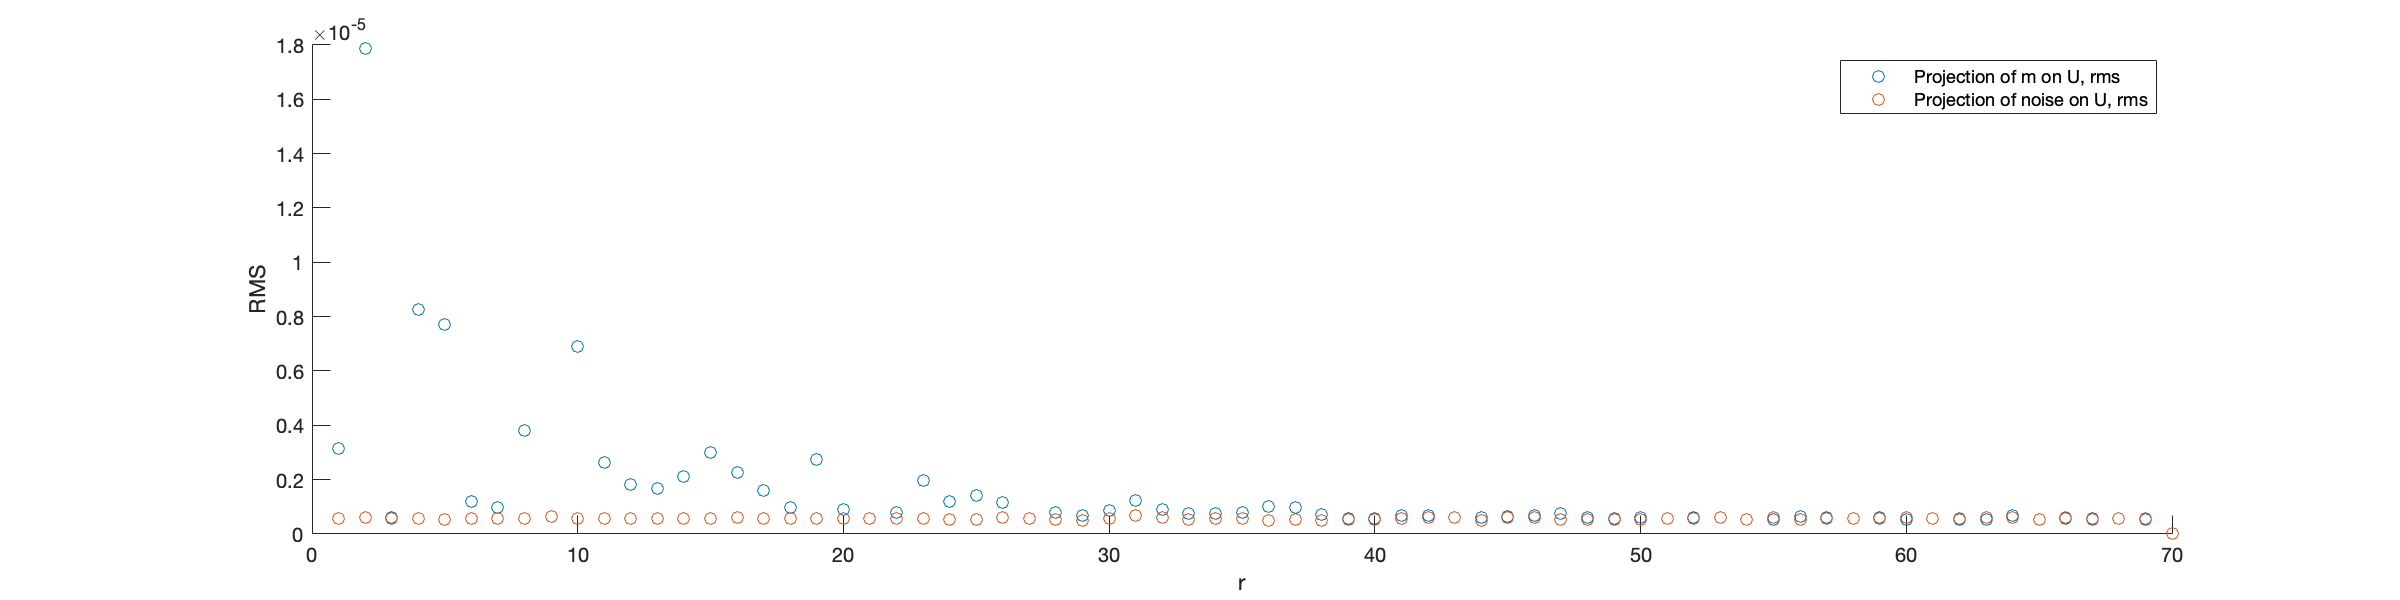

%% Project m and noiseref to U space.
m_on_U = U' * m;
noise_on_U = U' * noiseref;

mU_rms = sqrt(mean(m_on_U.^2,2));
nU_rms = sqrt(mean(noise_on_U.^2,2));

set(figure(5),'position',[0 100 3*plotwidth plotheight],'name','topoexample');clf;
hold on;
plot(mU_rms, 'o');
plot(nU_rms, 'o');
xlabel('r');
ylabel('RMS');
legend("Projection of m on U, rms","Projection of noise on U, rms");

As can be seen from the graph above, at a certain point (around 40) the noise starts to overlap with the measurement data, making it imposible to recognize from the noise.

## Using Morozov discrepancy principle for chosing r

% Another way to choose r is to use the Morozov discrepancy principle:
% |Ls − m|/|n| ≈ 1

for i = 1:Nfp
    L_trunc = V(:, 1:i)*pinv(S(1:i, 1:i))*U(:, 1:i)';
    s = L_trunc*m;
    morozov = norm(L*s - m, 2) / norm(noiseref, 2);
    if (morozov - 1) < 1e-6
        r = i;
        break;
    end
end
% The number starting from which the data is roughly as large as the amount of
% noise: 37

## Calculate estimated source and plot RMS amplitude of it on the cortical mesh

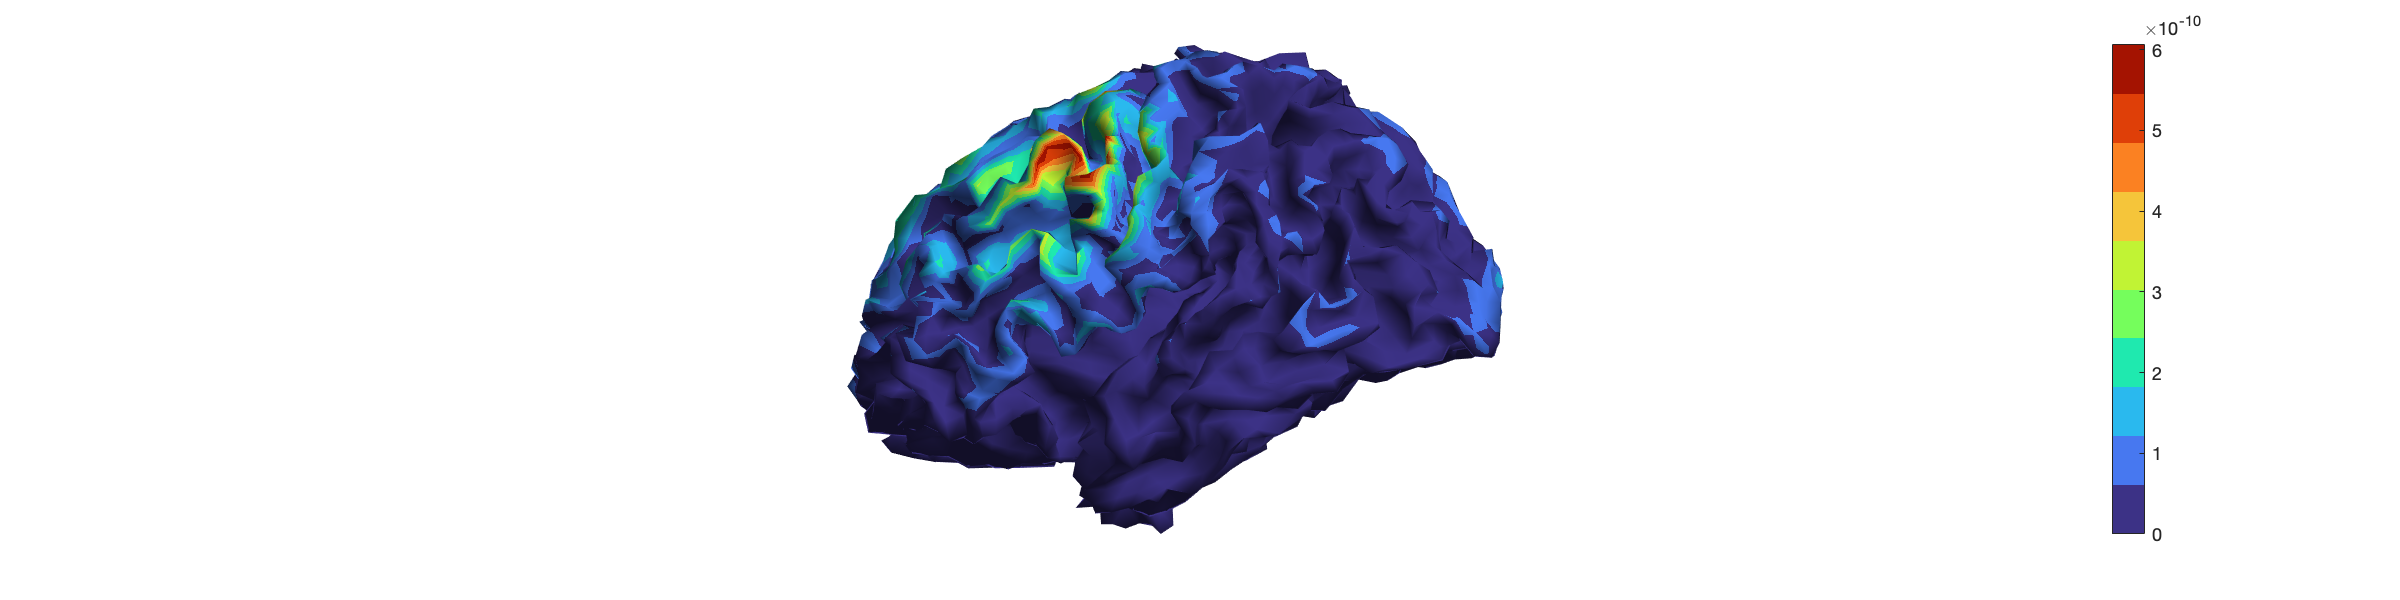

% using the r obtained from the Morozov approach, 
% compute the source estimate on the cortical mesh 
% and plot the RMS amplitude of the estimated source distribution on the cortex

L_r = V(:, 1:r)*pinv(S(1:r, 1:r))*U(:, 1:r)';
s_est = L_r*m;
s_est_rms = sqrt(mean(s_est.^2,2));

set(figure(6),'position',[0 100 3*plotwidth plotheight],'name','topoexample');clf;
PlotDataOnMesh(sfv, s_est_rms);

% we can say about the location of the one source